# Test Case - Engine

mdl = "Engine_Component_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end
Engine_Component_harness_setup

## Setup

simIn = Simulink.SimulationInput(mdl);

% Block parameters

simIn = setBlockParameter(simIn, mdl+"/Engine torque command", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Engine torque command", Time="1");
simIn = setBlockParameter(simIn, mdl+"/Engine torque command", After="0");

simIn = setBlockParameter(simIn, mdl+"/Axle clutch on off", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Axle clutch on off", Time="1");
simIn = setBlockParameter(simIn, mdl+"/Axle clutch on off", After="0");

simIn = setBlockParameter(simIn, mdl+"/Axle speed input", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Axle speed input", Time="1");
simIn = setBlockParameter(simIn, mdl+"/Axle speed input", After="0");

simIn = setBlockParameter(simIn, mdl+"/Axle torque input", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Axle torque input", Time="1");
simIn = setBlockParameter(simIn, mdl+"/Axle torque input", After="0");

% Initial conditions

simIn = setVariable(simIn, "initial.loadInertia_speed_rpm", 0);
simIn = setVariable(simIn, "initial.engine_speed_rpm", 0);

## Run Simulation

% Simulaton stop time
simIn = setModelParameter(simIn, StopTime = "1000");

% Run simulation
simOut = sim(simIn);

## Visualize Simulation Result

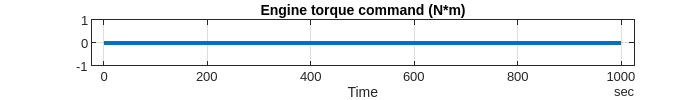

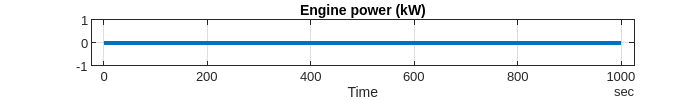

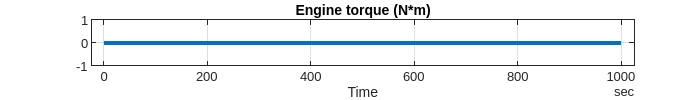

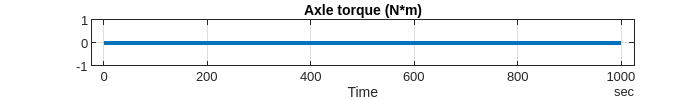

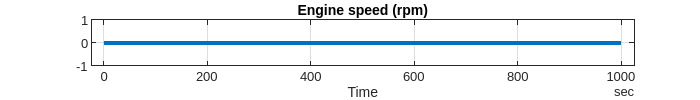

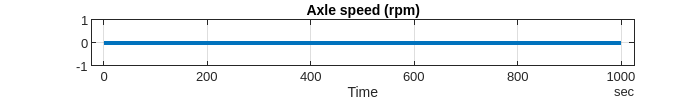

simData = extractTimetable(simOut.logsout);

Engine_Component_plotResults(SimData=simData, FigureHeight=100);

*Copyright 2021-2022 The Mathworks, Inc.*